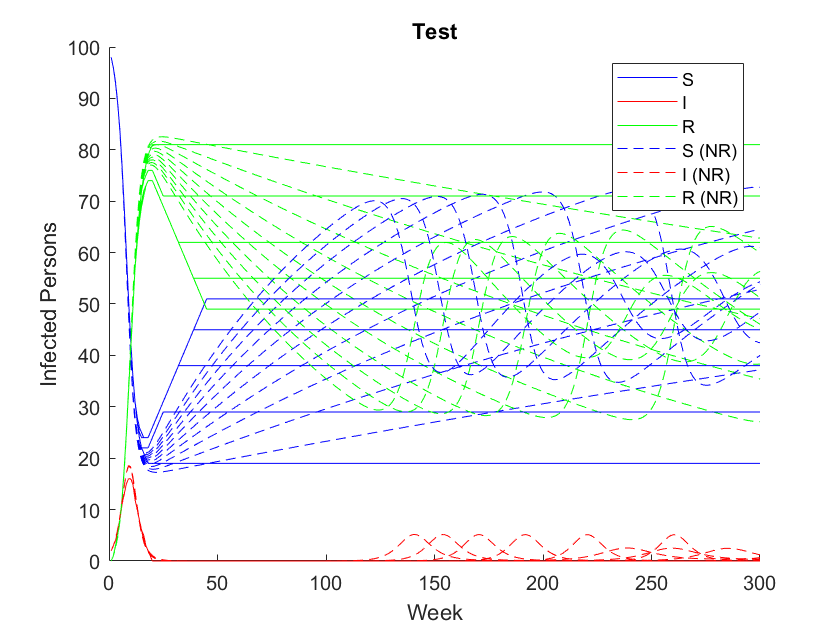

delta = 1.0000e-03

delta = 0.0020

delta = 0.0030

delta = 0.0040

delta = 0.0050

delta = 0.0060

delta = 0.0070

delta = 0.0080

delta = 0.0090

delta = 0.0100

clf;
hold on;
for delta = 0.001:0.001:0.01
    beta = 0.01; % Infection rate (New / Susceptible / Infected / day)
    gamma = 0.5; % Recovery rate (1 / day)
    delta % = 0.01;
    i_0 = 2;       % Initial count of infected persons
    
    % Define initial state
    s_0 = 100 - i_0;
    r_0 = 0;
    
    % Run simulation
    [S_fit, I_fit, R_fit, W_fit] = sir_simulate(s_0, i_0, r_0, beta, gamma, delta, 300);
    [S_nr, I_nr, R_nr, W_nr] = sir_simulate_noround(s_0, i_0, r_0, beta, gamma, delta, 300);
    
    
    % Plot the fitted simulation
    figure(1); % clf; hold on;
    % plot(tab_data_train.W, tab_data_train.I, 'b:', 'LineWidth', 3); label1 = "Measured";
    plot(W_fit, S_fit, 'b-'); label1 = "S";
    plot(W_fit, I_fit, 'r-'); label2 = "I";
    plot(W_fit, R_fit, 'g-'); label3 = "R";
    plot(W_fit, S_nr, 'b--'); label4 = "S (NR)";
    plot(W_fit, I_nr, 'r--'); label5 = "I (NR)";
    plot(W_fit, R_nr, 'g--'); label6 = "R (NR)";
    
    xlabel("Week")
    ylabel("Infected Persons")
    legend({label1, label2, label3, label4, label5, label6})
    title("Test")
end